# Mean-adjusted model

## Housekeeping

clear
close all

import mean.*

## Convenience functions

The `extremesFunc` function compresses any number of samples (draws from the posterior) into two numbers - the minimum and the maximum.

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];

medianFunc = @(x) median(x, 2)

medianFunc = function_handle with value:
    @(x)median(x,2)


## Number of Samples

numPresampled = 1000;

## Prepare data and a reduced-form model

The properties specific to the two-step FAVAR are as follows:

**trendType **– controls the the trend of each endogenous variable. could be

-     "**constant**" :intercept only

-     "**time**": intercept + linear

-     "**quadratic**" : intercept + linear+quadratic

**numRegimes **– controls the number of regimes for each endogenous variable.

**regimeSpans **– controls the periods of each regimes, note that if a regime has more sub periods and is "coming back", the sub periods has to be concatenated

**bounds **– controls upper and lower bounds for **"constant"** type trends for each regimes. Note that you have to list bounds for each regime also if the bounds are common for the regimes.

#### **Important notes**

For this particular model, the user cannot specify any exogenous variables. The only exogenous variables are the selected trends. The intercept property is also missing, as by construction it is assumed that all variables include one.


estimStart = datex.q(1972,1);
estimEnd = datex.q(2020,1);
estimSpan = datex.span(estimStart, estimEnd);

turningPoint1 = datex.q(2008,1);
turningPoint2 = datex.q(2014,4);  

inputTbx = tablex.fromFile("data/SV.csv");

meta = Meta( ...
    endogenousNames=["YER", "HICSA", "STN"], ...
    order=4, ...
    estimationSpan=estimSpan, ...
    trendType = ["time", "constant", "constant"],...
    numRegimes = [2, 2, 1],...    
    regimeSpans = { ...
                    {[datex.span(estimStart, turningPoint1), ...
                      datex.span(datex.shift(turningPoint2, 1), estimEnd)]}, ...
                    {datex.span(datex.shift(turningPoint1, 1), turningPoint2)} ...
                  }, ...
    bounds = {{[]}, {[1 4], [0 2]}, {[2 5]}}, ...              
    identificationHorizon=20 ...
);



## Specifying and loading input data


inputTbx = tablex.fromFile("data/SV.csv");
dataH = DataHolder(meta, inputTbx);


## Reduced form models

There is only estimator specific variable

**ScaleUp **used for scaling up the variance of the estimated constants


estimatorR = estimator.MeanAdjusted(meta,...
    ScaleUp = 100);

modelR = ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR ...
);

modelR.Estimator.Settings

ans =   MeanAdjusted with properties:

                   ScaleUp: 100
                    Burnin: 0
        StabilityThreshold: Inf
    MaxNumUnstableAttempts: 1000
                 Exogenous: [3×0 logical]
            BlockExogenous: 0
            Autoregression: [3×1 double]
                   Lambda1: 0.1000
                   Lambda2: 0.5000
                   Lambda3: 1
                   Lambda4: [3×0 double]
                   Lambda5: 1.0000e-03


modelR.initialize();
info = modelR.presample(numPresampled);


 Presampling from posterior (MeanAdjusted) [1000]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



## Running Unconditional forecast 

### Setting up the forecast range and run the forecast

fcastStart = datex.shift(modelR.Meta.EstimationEnd,1); 
fcastEnd = datex.shift(modelR.Meta.EstimationEnd, 12); 
fcastSpan = datex.span(fcastStart, fcastEnd);

fcastStart, fcastEnd

fcastStart = datetime
   2020-Q2


fcastEnd = datetime
   2023-Q1



fcastTbx1 = modelR.forecast(fcastSpan);
fcastPrctileTbx1 = tablex.apply(fcastTbx1, prctileFunc);

### Visualize the unconditional forecast

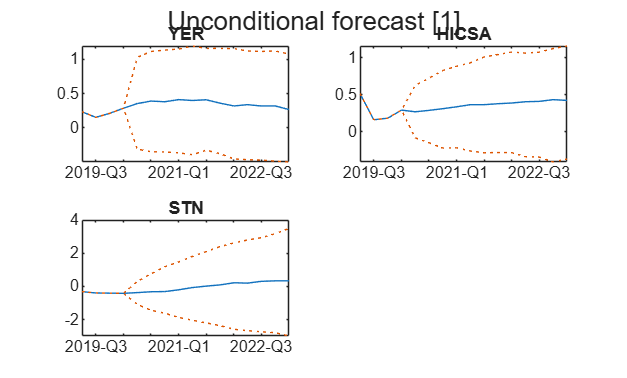

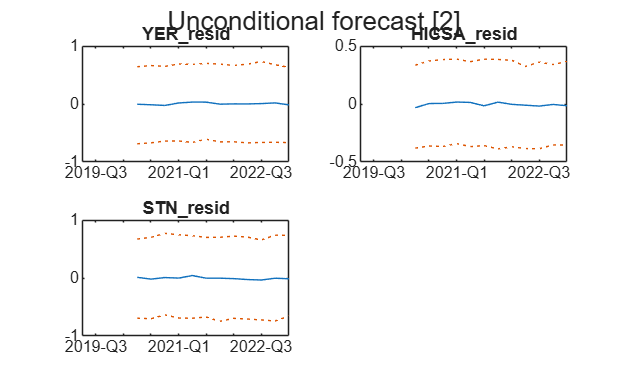

ans = 1×2 cell array
    {1×1 Figure}    {1×1 Figure}


chartpack.forecastPercentiles( ...
    fcastPrctileTbx1, modelR, FigureTitle ="Unconditional forecast")